# Pakete sinboliko matematikoaren tutoriala

**Autorea: **Jon Asier Bárcena

Dokumentu honetan azalduko dut nola erabili Matlabeko [Symbolic Math Toolbox](https://es.mathworks.com/products/symbolic.html). Pakete hori balio du eragiketa sinbolikoak egin ahal izateko; hots, eragiketak egin ahal izateko hurbilpenik egin gabe. Zenbakizko kalkuluarekin alderatuz hainbat desabantaila ditu:

- Eragiketak egiteko zenbakizko kalkulua baino denbora gehiago behar du, biribilketarik egiten ez duelako. Hori dela eta, **pakete hau bereziki akademikoa da, eta enpresen munduan gutxi erabiltzen da**. 

- Paketeak memoria gehiago behar du; izan ere, matematikako irakasgaian ikusitako trikimailu guztiak eskuz sartu behar dira. 

- **Pakete sinbolikoa taula handi bat bezalakoa da**. Hori dela eta, zure eragiketa taula horretan ez badago, ez dizu emaitzik emango. Hau berereziki igertzen da ekuazio diferentzialak ebazteko orduan, baina erroen bilaketetarako ere horrelakoak gertatzen dira.

 Aldiz, pakete honek badu abantaila garrantzitsu bat:

- Emaitza zehatzak ematen ditu. 

Gogoratu pakete hori ez dagoela Matlabeko oinarrizko programan, luzapen bat da **deskargatu behar dena** (EHU-ko ordenagailuetan eta MATLAB online jada dago deskargatuta)**. **Hori egiteko, Matlab deskargatzeko orduan klikatu behar duzu pakete hori nahi duzula. Bestela, deskarga dezakezu programatik, desinstalatu eta instalatu gabe: 

Home --> Add-Ons --> Get Add-Ons --> search for add-ons (Symbolic Math Toolbox idatzi)-->Install (edo Sign in to Install)

clear all

## 1-Funtzio sinbolikoak.

### 1.1-Aldagai sinbolikoak

Hasteko, pakete sinbolikoa erabili ahal izateko, aldagai bat sinbolikoa dela deklaratu behar duzu. Hortik aurrera kontuz ibili behar zara aldagai hori erabiltzeko. 

syms x

Honekin eragiketak egin daitezke ohiko sintaxia erabiliz:

x^3+2*x-x^3

$$ans = 2\,x$$

x^2/x

$$ans = x$$

(x^2+2*x+1)/(x+1)

$$ans = \frac{x^{2}+2\,x+1}{x+1}$$

Gainera, pakete sinbolikoa lan egiten du funtzio elementalekin, 

(sin(x))^2+(cos(x))^2

$$ans = {\cos\left(x\right)}^{2}+{\sin\left(x\right)}^{2}$$

exp(log(x))

$$ans = x$$

### 1.2-Espresioak sinplifikatzen

Ohartu pakete sinbolikoa ez dituela sinplifikazio ohizko teknikak zuzenean aplikatzen, bakarrik oso ebidentea denean. Hori egiteko **simplify** erabili behar da, eta paketeak egiten duena da ezagutzen dituen sinplifikatzeko era guztiak testeatu:

simplify((x^2+2*x+1)/(x+1))

$$ans = x+1$$

simplify((sin(x))^2+(cos(x))^2)

$$ans = 1$$

simplify(exp(log(x)))

$$ans = x$$

### 1.3-Aldagaia errerala bihurtzen eta logaritmoa

Programari ez badiogu ezer esaten, suposatuko du zenbaki konplexuekin ari garela lan egiten. Egoera askotan hori ez du eraginik, baina beste askotan bai. Ohartu log(exp(x)) idatziz gero ez duela sinplifikatzen:  

simplify(log(exp(x)))

Hori ez da akats bat. Arrazoia da log ematen dizula zuzen errealatik gertuen dagoen esponentzialaren alderantzizkoa (gogoratu esponentziala, planu konplexuan periodikoa da: izan ere $e^{x+yi}=e^x(\cos(y)+i\sin(y))$, esponentzial konplexua, definizioz, $e^z=\sum_{k=0}^\infty\frac{z^k}{k!}$baita). 

Hortaz, esan behar diogu aldagai erreal batekin ari garela lanean. Hori MATLAB-i esateko, **assume **komandoa erabili behar dugu:

assume(x,"real")

$$ans = x$$

simplify(log(exp(x)))

Orain bai egiten dizuela ondo. Antzeko gauzak gerta daitezke arku sinu/kosinu/tangente funtzioekin. Assume funtzioari buruz gehiago jakiteko, irakurri dokumentazioa. Bide batez, posible da egin dituzun hipotesiak kentzen **assume(aldagaia, clear) **idatziz:

assume(x,"clear")

## 2-Funtzio sinbolikoak

### 2.1-Funtzioak definitzen eta ebaluatzen

MATLAB-en funtzio sinbolikoak defini daitezke. Horretarako:

funtzioa(aldagaia)=esperezioa erabili behar da. 

Adibidez:

f(x)=x^2+2*x+1;
g(x)=sin(x);

Funtzioak, ebalua daitezke:

f(2)

$$ans = 9$$

f(3.1)

$$ans = \frac{1681}{100}$$

g(pi)

$$ans = 0$$

Ohartu pakete sinbolikoa erabiltzen ari zarenean, **pi** aldagai sinbolikoa bihurtzen duela. MATLAB-ek pakete sinbolikoa ari zarela lan egiten suposatzen du zenbaki sinboliko batekin eragita bat egiten duzunean, edo funtzio sinboliko batekin konposatzen duzunean.

### 2.2-Funtzioen konposaketa

Pakete sinbolikoan posible da funtzioak konposatzea. Adibidez:

h1(x)=f(g(x))

$$h1(x) = {\sin\left(x\right)}^{2}+2\,\sin\left(x\right)+1$$

h2(x)=g(f(x))

$$h2(x) = \sin\left(x^{2}+2\,x+1\right)$$

Funtzio berri horiek ebalua daitezke:

h1(pi/2)

$$ans = 4$$

h2(pi/2)

$$ans = -\sin\left(\frac{\pi^{2}}{4}+1\right)$$

### 2.3-Funtzioak deribatzen

Matlabek funtzio sinbolikoak deriba ditzake **diff **komandoa erabiliz. Aldagai bateko funtzioa erabiltze duzuenean sarrera bezala, ez duzu espezifikatu behar zein aldagaiarekiko ari garen deribatzen, aldagai horrekiko deribatu baitu:

diff(h1)

$$ans(x) = 2\,\cos\left(x\right)+2\,\cos\left(x\right)\,\sin\left(x\right)$$

diff(h2)

$$ans(x) = \cos\left(x^{2}+2\,x+1\right)\,\left(2\,x+2\right)$$

 Gainera, esan dezakezu zenbat alditan nahi duzun deribatzea (defektuzko balioa 1 izango da):

diff(h1,4)

$$ans(x) = -8\,{\cos\left(x\right)}^{2}+8\,{\sin\left(x\right)}^{2}+2\,\sin\left(x\right)$$

diff(h2,4)

$$ans(x) = \sin\left(x^{2}+2\,x+1\right)\,{\left(2\,x+2\right)}^{4}-8\,\cos\left(x^{2}+2\,x+1\right)\,{\left(2\,x+2\right)}^{2}-12\,\sin\left(x^{2}+2\,x+1\right)-\cos\left(x^{2}+2\,x+1\right)\,\left(2\,x+2\right)\,\left(8\,x+8\right)$$

Gogoratu lortutako emaitzak sinplifika daitezkeela:

simplify(diff(h1,4))

$$ans(x) = 16\,{\sin\left(x\right)}^{2}+2\,\sin\left(x\right)-8$$

simplify(diff(h2,4))

$$ans(x) = 16\,\sin\left({\left(x+1\right)}^{2}\right)\,{\left(x+1\right)}^{4}-32\,\cos\left({\left(x+1\right)}^{2}\right)\,{\left(x+1\right)}^{2}-12\,\sin\left({\left(x+1\right)}^{2}\right)-\cos\left({\left(x+1\right)}^{2}\right)\,\left(2\,x+2\right)\,\left(8\,x+8\right)$$

Azknik, posible da deribatua funtzio bezala gordetzea nahi duzun izenarekin, adibidez gero ebaluatzeko:

dh1(x)=diff(h1)

$$dh1(x) = 2\,\cos\left(x\right)+2\,\cos\left(x\right)\,\sin\left(x\right)$$

dh1(pi/2)

$$ans = 0$$

deribatuh2(x)=diff(h2)

$$deribatuh2(x) = \cos\left(x^{2}+2\,x+1\right)\,\left(2\,x+2\right)$$

deribatuh2(pi)

$$ans = \cos\left(\pi^{2}+1\right)\,\left(2\,\pi +2\right)$$

### 2.4-Taylorren hurbilpenak kalkulatzen

Posible da funtzio baten Taylorren segida [taylor](https://es.mathworks.com/help/symbolic/sym.taylor.html) komandoa erabiliz. Funtzio honen dokumentazioa irakurtzea zuen lana izango da, eta ariketa bat egongo da honen inguruan. 

### 2.5- Grafikoak

Pakete sinbolikoan funtzioen grafikak erabil daiteke. Horretarako, **fplot **erabili daiteke, funtzio anonimoekin bezala funtzionatzen duena:

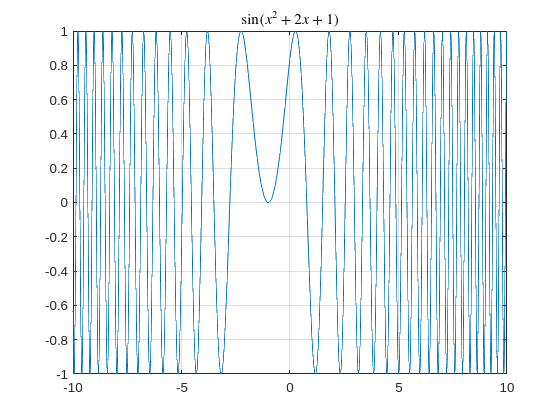

fplot(h2,[-10 10]) %Grafikoa (-10,10) tartean egiteko, fplot-en barruan ere jar daiteke. 
title("$\sin(x^2+2x+1)$","Interpreter","latex")
grid on 

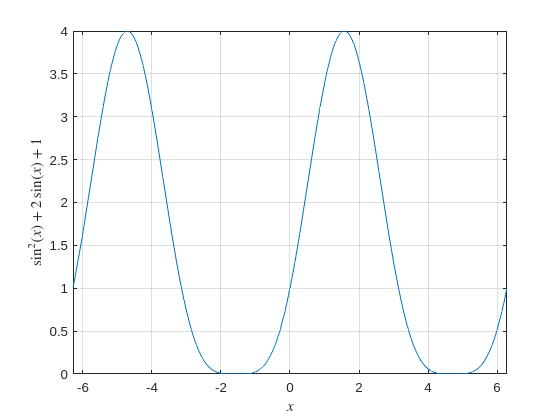

fplot(h1)
xlabel("$x$","Interpreter","latex")
ylabel("$\sin^2(x)+2\sin(x)+1$","Interpreter","latex")
grid on 
xlim([-2*pi 2*pi])

## 3-Kalkulu sinbolikoa eta puntu higikorreko zenbakiak

Aldagai sinbolikoekin lan egitea balio zehatzak ematen digu, baina batzuk guk hurbilpen nahi dugu matlabeko ohiko formatuan, 64 biteko puntu higikorreko formatuan. Hurbilpenak interegarriak dira Matlaben ohiko eragiketak egin ahal izateko, eta batzuetan beharrezkoak dira zenbakiaren hurbilpen bat izako (deribatuh2(pi)-ren kasuan, adibidez) Horretarako, nahikoa da **double** erabiltzea, zenbaki sinboliko bat koma higidurako zenbakira pasatzen duena. 

double(f(3.1))

ans = 16.8100

double(h2(pi/2))

ans = 0.3201

double(deribatuh2(pi))

ans = -1.0407

Gainera, **pi** komandoa erabiltzean kontuz ibili behar da, eragiketa batzuk egitean pakete sinbolikia jada ez baitu $\pi$ bezala irakurtzen. 

f(sin(pi))

$$ans = \frac{1645504557321206445187347003716848840571631067937595507065292849}{1645504557321206042154969182557350504982735865633579863348609024}$$

deribatuh2(sqrt(pi))

$$ans = \frac{6243011064919989\,\cos\left(\frac{38975187156713415108362971760121}{5070602400912917605986812821504}\right)}{1125899906842624}$$

Horrelako gauzengatik kontuz ibili behar da pakete sinbolikoa erabiltzeko orduan, eta horregatik hobe da orokorrean koma higidurako zenbakiak erabiltzea. Imajina zein izan daiteke koste konputazionala zenbaki MATLAB zenbaki horiekin egiten duenean lan. Lehenego kasuan dagoen arazoa, bide batez, da MATLAB-entzat sin(pi) 1.1102e-16 inguru dela, eta bigarren kasuan dezimal guztietan hartzen dituela kontuan. Matlabi esateko zehatz mehatz $\pi$-rekin ari garela lan egiten, **sym(pi) **idatzi behar da, kasu horretan, puntu horretatik aurrera $\pi$ aldagai sinbolikoarekin egingo baitu lan:

f(sin(sym(pi)))

$$ans = 1$$

deribatuh2(sqrt(sym(pi)))

$$ans = -\cos\left(2\,\sqrt{\pi }+1\right)\,\left(2\,\sqrt{\pi }+2\right)$$

Azkenik, syms hori ere erabil daiteke zenbaki dezimalekin lan egiteko orduan:

sym(1/3)+ sym(1/6)

$$ans = \frac{1}{2}$$

sym(25/81-17/25)

$$ans = -\frac{752}{2025}$$

## 4-Pakete sinbolikoa eta matematikako gradua. 

Matemtatika pakete sinbolikoa baditu beste funtzio batzuk, adbidez analisirako  **integrate**, **gradient, hessian, jacobian, dsolve **esate baterako**;**  aljebra linealerako:** jordan, eig, inv, pinv **adibidez**; **eta konbinatoriarako** Fibonnaci **esate baterako**. **Gainera, [beste funtzio](https://es.mathworks.com/help/symbolic/referencelist.html?type=function) asko daude erabilgarri suerta zaizkizuenak. Ohartu horietako batzuk erabil daitezkeela balio sinbolikoetarako edo koma higikorreko zenbakiak; adibidez, **linsolve, max, gamma, etc.** Animatzen dizuet zuen kabuz arakatzea egin ditzakeen gauzak, irakasgai honetarako erabilgarriak direnak soilik azalduko baitizuegu. Posible da zuentzat erabilgarria den zeozer aurkitzea. 